s = tf('s');
P_11 = (0.8889 * (s+3.834) * (s-3.834)) / (s^2 * (s-4.427) * (s+4.427));
P_12 = (-1.333*s^2) / (s^2 * (s-4.427) * (s+4.427));
P_21 = -1.333 / ((s-4.427) * (s+4.427));
P_22 = 8 / ((s-4.427) * (s+4.427));
P = [P_11 P_12; P_21 P_22]

P =
 
  From input 1 to output...
       0.8889 s^2 - 13.07
   1:  ------------------
         s^4 - 19.6 s^2
 
         -1.333
   2:  ----------
       s^2 - 19.6
 
  From input 2 to output...
         -1.333 s^2
   1:  --------------
       s^4 - 19.6 s^2
 
           8
   2:  ----------
       s^2 - 19.6
 
Continuous-time transfer function.



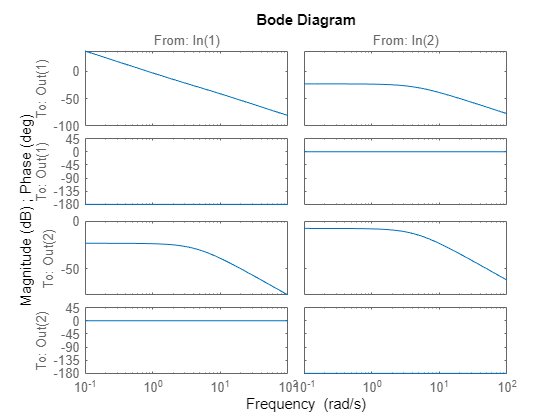

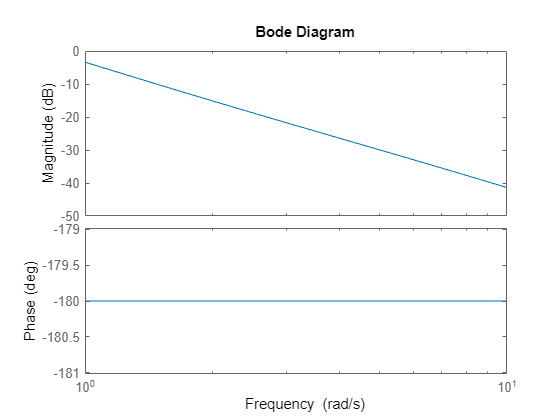


bode(P)

A3 =  [0    1.0000000000000         0                      0
       0                  0   -3.26666666666666667         0
       0                  0         0                      1.0000000000000000
       0                  0   19.60000000000000000         0                  ];
B3 = [ 0                                          0
       0.8888888888888888889   -1.33333333333333333
       0                                          0
       -1.333333333333333333    8.00000000000000000 ];
C3 = [1 0 0 0; 0 0 1 0]; 
D3 = zeros(2,2);
P3 = ss(A3,B3,C3,D3);

zpk(P3) % verify it works!

ans =
 
  From input 1 to output...
       0.88889 (s+3.834) (s-3.834)
   1:  ---------------------------
         s^2 (s-4.427) (s+4.427)
 
             -1.3333
   2:  -------------------
       (s-4.427) (s+4.427)
 
  From input 2 to output...
       -1.3333 (s^2 + 2.809e-15)
   1:  -------------------------
        s^2 (s-4.427) (s+4.427)
 
                8
   2:  -------------------
       (s-4.427) (s+4.427)
 
Continuous-time zero/pole/gain model.



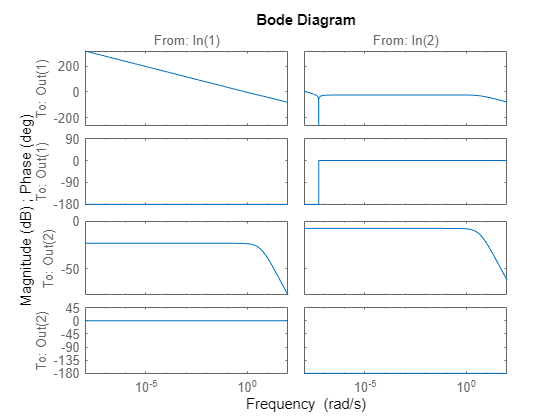

bode(P3)

K = 1

K = 1

P_app1 = 2 / (3 * s ^2)

P_app1 =
 
    2
  -----
  3 s^2
 
Continuous-time transfer function.



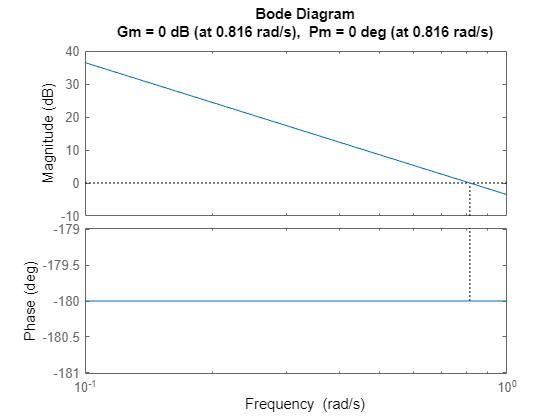

margin(K*P_app1)

a = (1 + sind(50)) / (1 - sind(50))

a = 7.5486

w = 0.816

w = 0.8160

tau = 1 / (w * sqrt(a))

tau = 0.4460

C_1 = (K / sqrt(a)) * ((1+a * tau * s)/ (1 + tau * s))

C_1 =
 
  1.225 s + 0.364
  ---------------
    0.446 s + 1
 
Continuous-time transfer function.



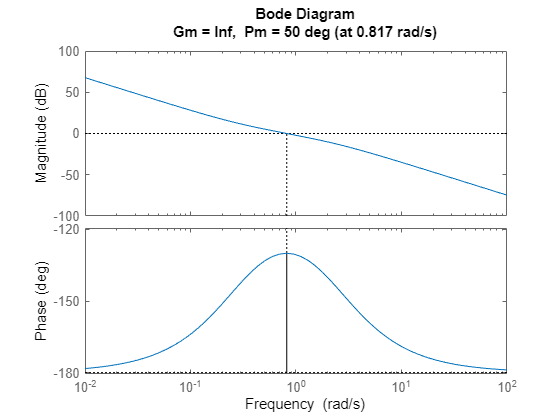

margin(P_app1 * C_1)

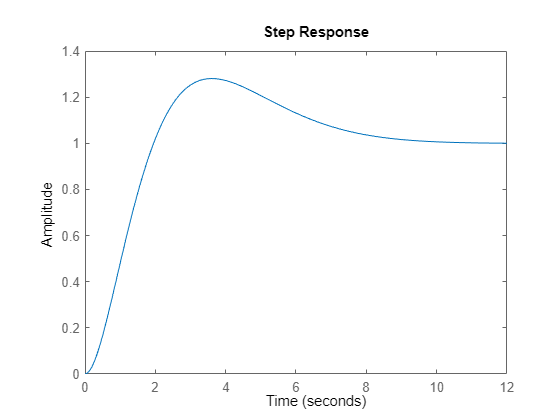

step(P_app1 * C_1/ (1 + P_app1 * C_1))

P_app2 = 6 / (s^2 - 14.7)

P_app2 =
 
      6
  ----------
  s^2 - 14.7
 
Continuous-time transfer function.



[M, N, X, Y] = coprime(P_app2, 5);
zpk(M);
zpk(N);
zpk(X);
zpk(Y);
evalfr(minreal(Y), 0);
evalfr(minreal(N), 0);

Q = evalfr(Y, 0) / evalfr(N, 0)

Q = 56.6167

C_2 = (X + M * Q) / (Y - N * Q);
C_2 = minreal(C_2);

7 states removed.


zpk(C_2)

ans =
 
  56.617 (s+1.961) (s+3.753)
  --------------------------
           s (s+30)
 
Continuous-time zero/pole/gain model.



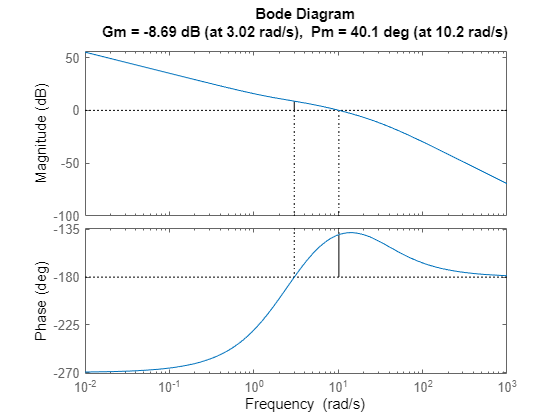

margin(P_app2 * C_2)

phi = 50 - 40.1

phi = 9.9000

w = 10.2;
a = (1 + sind(phi)) / (1-sind(phi));

tau = 1 / (w * sqrt(a))

tau = 0.0824

C_2 = zpk(minreal(C_2 / sqrt(a) * (1 + a * tau * s ) / ( 1 +tau * s)))

2 states removed.

C_2 =
 
  67.354 (s+8.574) (s+3.753) (s+1.961)
  ------------------------------------
           s (s+30) (s+12.13)
 
Continuous-time zero/pole/gain model.



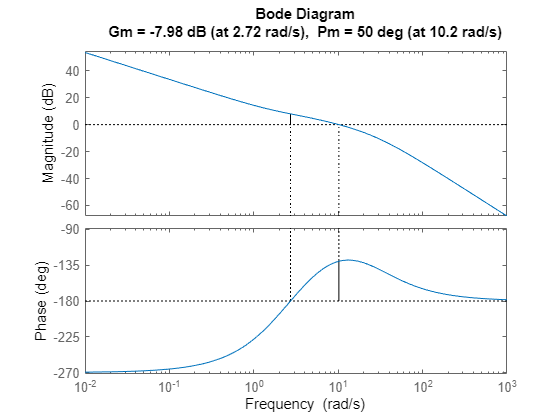

margin(P_app2 * C_2)

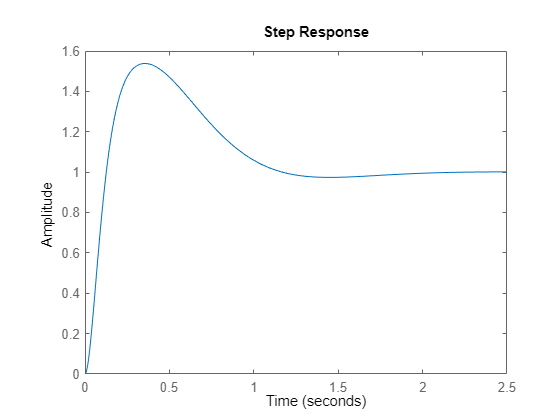

step( P_app2 * C_2 / (1 + P_app2 * C_2))

C = [C_1 0;0 C_2]

C =
 
  From input 1 to output...
       2.7475 (s+0.297)
   1:  ----------------
          (s+2.242)
 
   2:  0
 
  From input 2 to output...
   1:  0
 
       67.354 (s+8.574) (s+3.753) (s+1.961)
   2:  ------------------------------------
                s (s+30) (s+12.13)
 
Continuous-time zero/pole/gain model.



L = minreal(P3 * C);
T = minreal(L * inv(eye(2) + L));

10 states removed.


zpk(T)

ans =
 
  From input 1 to output...
       -5.7202e-12 (s-4.269e11) (s+3.94) (s+0.297) (s^2 + 5.572s + 15.97) (s^2 + 32.62s + 405.2)
   1:  -----------------------------------------------------------------------------------------
       (s+5.482) (s+0.8278) (s^2 + 1.446s + 0.6753) (s^2 + 5.54s + 12.13) (s^2 + 31.08s + 497.5)
 
       5.1598e-13 (s-7.1e12) (s+30) (s+12.13) (s+0.297) (s+0.0002998) (s^2 - 0.0002998s + 9.119e-08)
   2:  ---------------------------------------------------------------------------------------------
         (s+5.482) (s+0.8278) (s^2 + 1.446s + 0.6753) (s^2 + 5.54s + 12.13) (s^2 + 31.08s + 497.5)
 
  From input 2 to output...
              -89.805 (s+8.574) (s+3.753) (s+2.242) (s+1.961) (s-1.152e-05) (s+1.152e-05)
   1:  -----------------------------------------------------------------------------------------
       (s+5.482) (s+0.8278) (s^2 + 1.446s + 0.6753) (s^2 + 5.54s + 12.13) (s^2 + 31.08s + 497.5)
 
                538.83 (s+8.574) (s+3.753) (s+1.961) (

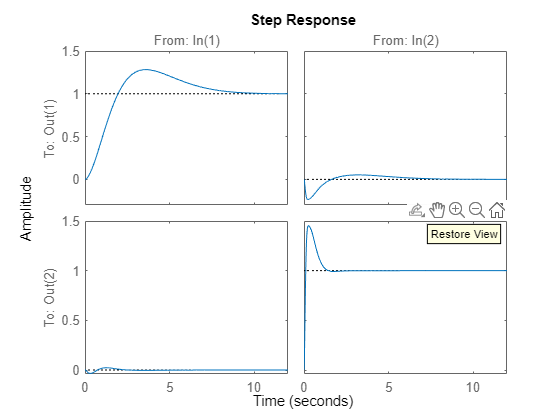

step(T)

evalfr(T, 0)

ans =     1.0000    0.0000
   -0.0000    1.0000
